# Part 4: Stranger vs. Cagemate

Analyses of Experiment 4

## A. Variables for SHK-RWD comparisons

xticklabels = {'STR' 'CAG1' 'CAG2'};

 cof_str_ind = find(strcmp(rdb.experiment, 'str'));
 cof_iso1_ind = find(strcmp(rdb.experiment, 'org') & rdb.condition(:,2)' == 24);
 cof_iso2_ind = find(strcmp(rdb.experiment, 'cof')' & rdb.condition(:,4) == 0 & rdb.condition(:,2) == 24);
 
 cofind = cell(3,1);
 cofind{1} = cof_str_ind;
 cofind{2} = cof_iso1_ind;
 cofind{3} = cof_iso2_ind;
 
 for i = 1:3
     scofind(i) = length(cofind{i});
 end

 
%[u_paircodes, ia_pairs, ic_pairs] = unique(rdb.paircode(exp_ind));
% condvec = [5 2 4]; % 1 min 45 min 1 day
 phystypes = [-1 1 2 3];
 betypes = phystypes;%oops. Used phystypes a few places. But I meant betypes. Now they'll be the same. ]]></w:t></w:r></w:p><w:p><w:pPr><w:sectPr/></w:pPr></w:p><w:p><mc:AlternateContent xmlns:mc="http://schemas.openxmlformats.org/markup-compatibility/2006"><mc:Choice Requires="R2018b"><w:pPr><w:pStyle w:val="heading2"/><w:jc w:val="left"/></w:pPr></mc:Choice><mc:Fallback><w:pPr><w:pStyle w:val="heading"/><w:jc w:val="left"/></w:pPr></mc:Fallback></mc:AlternateContent><w:bookmarkStart w:name="MW_H_3B86E0E3" w:id="H_3B86E0E3"/><w:r><w:t>1.1 Physical interactions protocol</w:t></w:r><w:bookmarkEnd w:id="H_3B86E0E3"/></w:p><w:p><w:pPr><w:pStyle w:val="text"/><w:jc w:val="left"/></w:pPr><w:r><w:t></w:t></w:r></w:p><w:p><w:pPr><w:pStyle w:val="code"/></w:pPr><w:r><w:t><![CDATA[%open Desktop\Degu\reunion\Lidhar_ReunionMotivation_Figure1.pptx]]></w:t></w:r></w:p><w:p><w:pPr><w:sectPr/></w:pPr></w:p><w:p><mc:AlternateContent xmlns:mc="http://schemas.openxmlformats.org/markup-compatibility/2006"><mc:Choice Requires="R2018b"><w:pPr><w:pStyle w:val="heading2"/><w:jc w:val="left"/></w:pPr></mc:Choice><mc:Fallback><w:pPr><w:pStyle w:val="heading"/><w:jc w:val="left"/></w:pPr></mc:Fallback></mc:AlternateContent><w:bookmarkStart w:name="MW_H_F38EEFDC" w:id="H_F38EEFDC"/><w:r><w:t>1.2 Physical interactions: combined</w:t></w:r><w:bookmarkEnd w:id="H_F38EEFDC"/></w:p><w:p><w:pPr><w:pStyle w:val="code"/></w:pPr><w:r><w:t><![CDATA[% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 1.1 Total physical interaction data
behaviortypes = {'Agonistic' 'Grooming' 'Rear-sniffing' 'Face-to-face'};

## B. Physical Interactions

### B.1  Physical interactions, combined

septime_mat = nan(max(scofind),length(cofind), length(phystypes));
 for i = 1:max(scofind)
    for j = 1:length(cofind)        
         if length(cofind{j}) >= i
             septime_mat(i,j,1:length(phystypes)) = sum(rdb.sumbehav(cofind{j}(i),:),1);
         end
    end
 end
 
 %something is wrong with one of the sessions (probably the recorded session start/end times)
 % for now we will remove
% septime_mat(end, end, :) = nan;
 

Figure of total physical interaction data

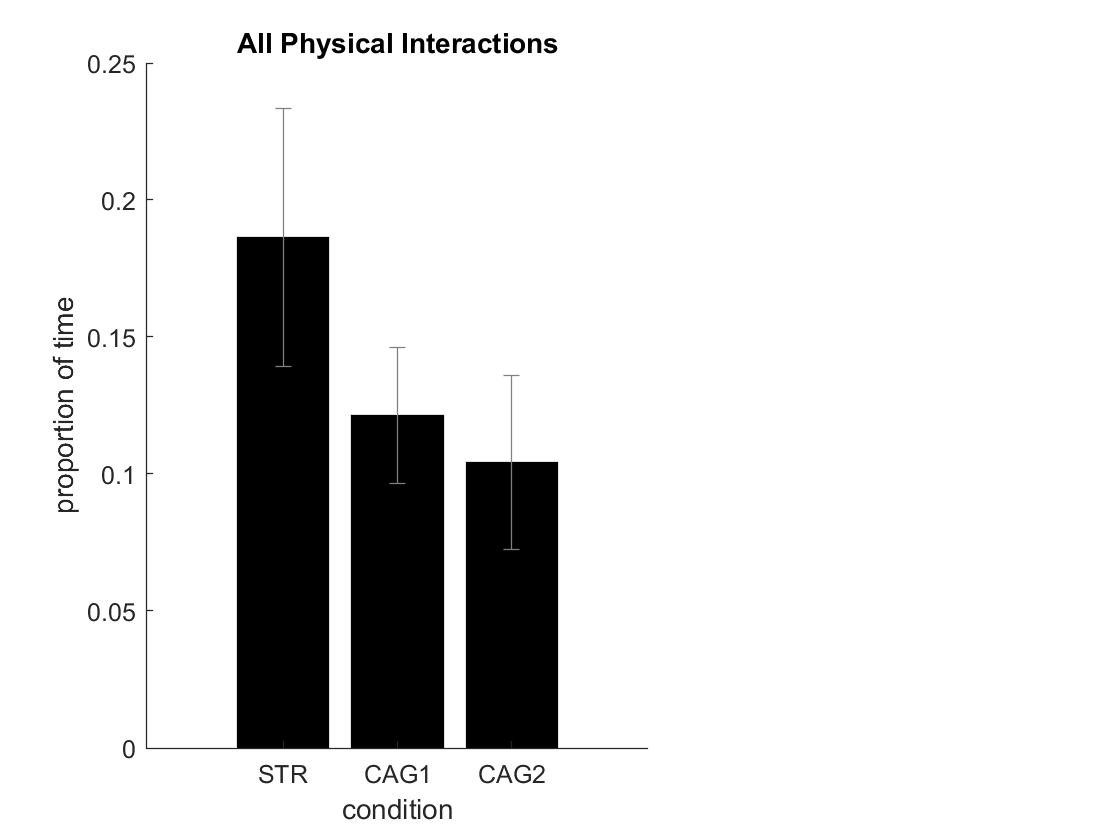

 stm_all = nansum(septime_mat,3);
 
% not normalized:
 figure
 f2A = subplot(1,5,1:3);
 bar(1:3, nanmean(stm_all), 'FaceColor', 'k');
 hold on;
 eb = errorbar(1:3, nanmean(stm_all), nanstd(stm_all)/sqrt(size(septime_mat,1)-1), 'LineStyle', 'none', 'Color', [.5 .5 .5]);
 set(f2A, 'XTickLabel', xticklabels);
 set(get(f2A, 'XLabel'), 'String', 'condition');
 set(get(f2A, 'YLabel'), 'String', 'proportion of time');
 set(get(f2A, 'Title'), 'String', 'All Physical Interactions');
 box off

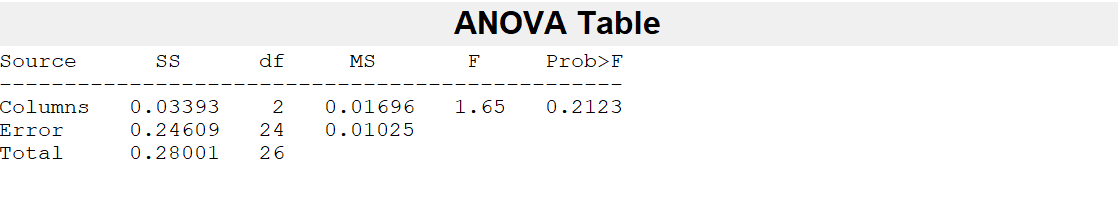

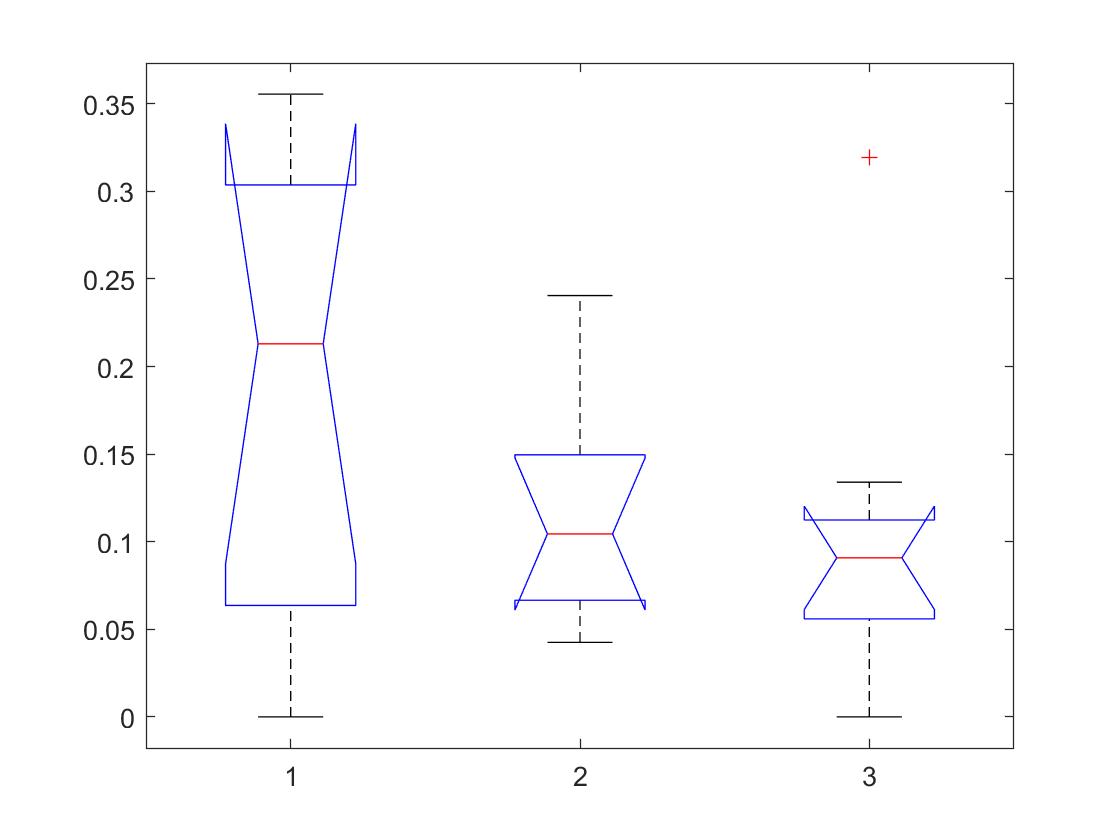

 [p, table] = anova1(stm_all);

 
 [a b] = ttest2(stm_all(:,1), [stm_all(:,3) ; stm_all(:,2)])

a = 0

b = 0.0816

### B.2 Interaction types

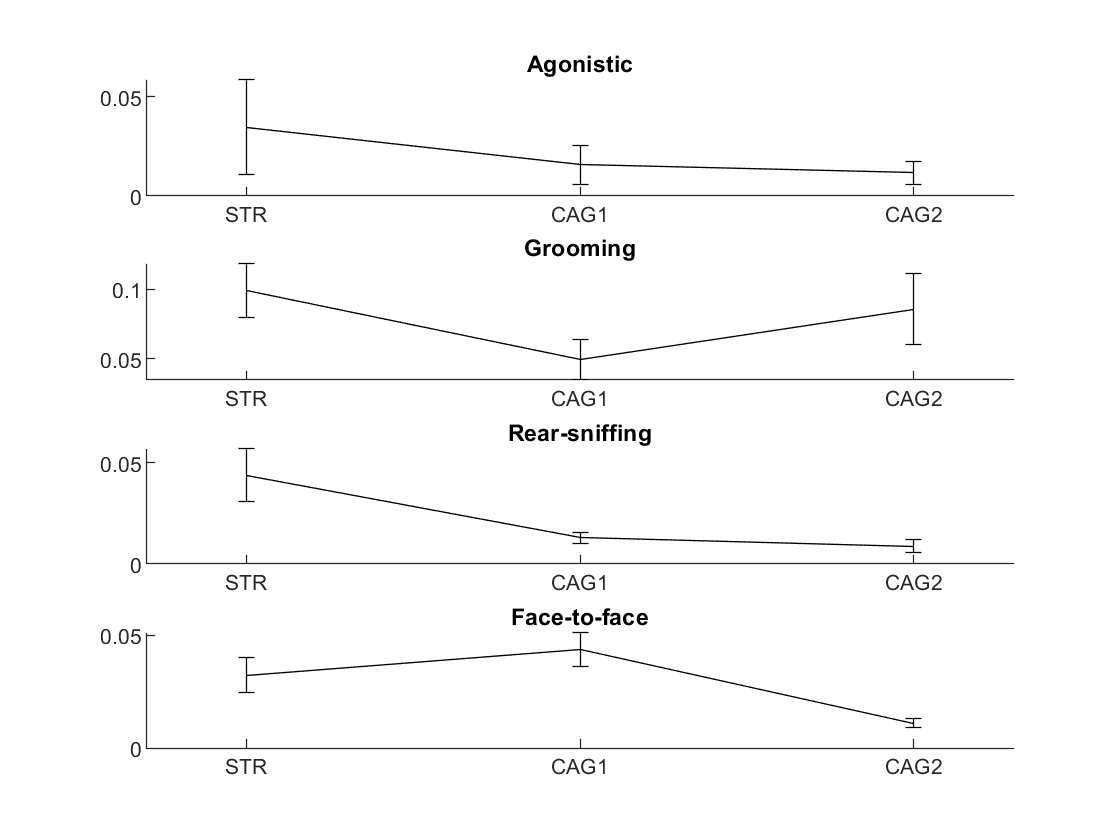



figure
 for i = 1:4
%     f2B = subplot(4,3,i*3);
    f2B = subplot(4,1,i);
     %bar(1:3, nanmean(septime_mat(:,:,i)));
     hold on
     e_sub = errorbar(1:3, nanmean(septime_mat(:,:,i)), nanstd(septime_mat(:,:,i))/sqrt(size(septime_mat,1)-1), 'k'); %'LineStyle', 'none');
%    ax = gca;
%    ax.Clipping = 'off';
    set(f2B, 'XTick', [1:3]);
     set(f2B, 'XTickLabel', xticklabels);
  %  set(get(f1B, 'XLabel'), 'String', 'condition');
 %   set(get(f1B, 'YLabel'), 'String', 'proportion of time');
    set(get(f2B, 'Title'), 'String', behaviortypes{i});
    set(get(e_sub, 'Parent'), 'XLim', [.7 3.3]);
     box off
 end

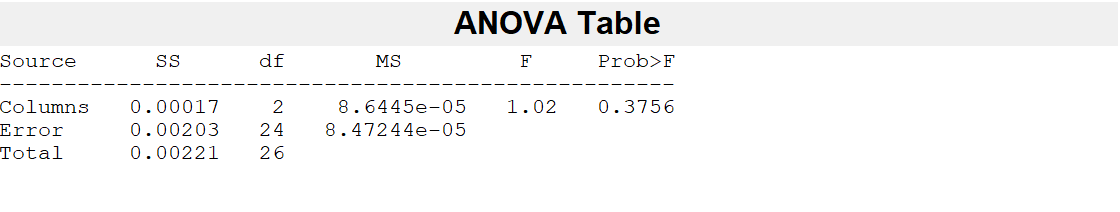

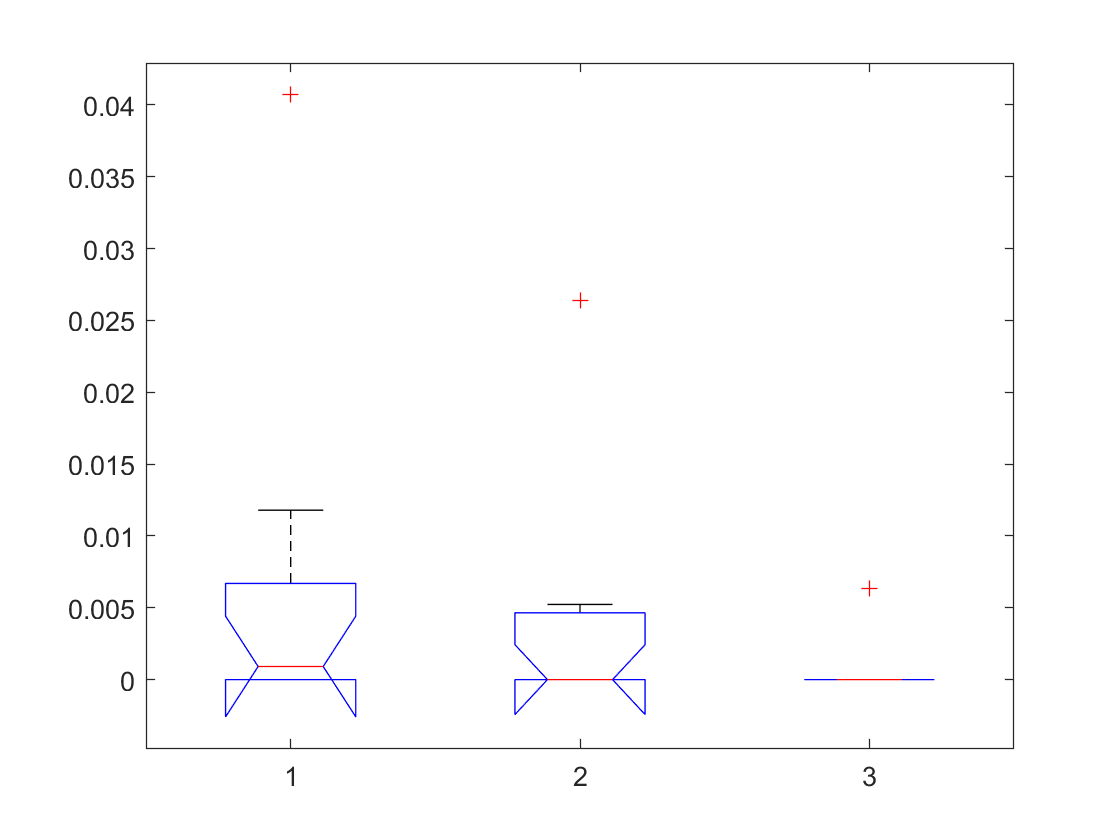

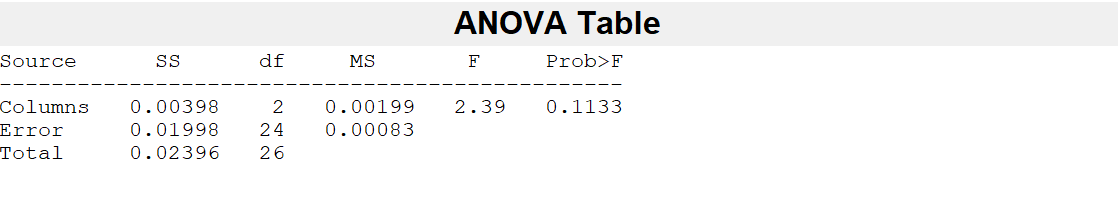

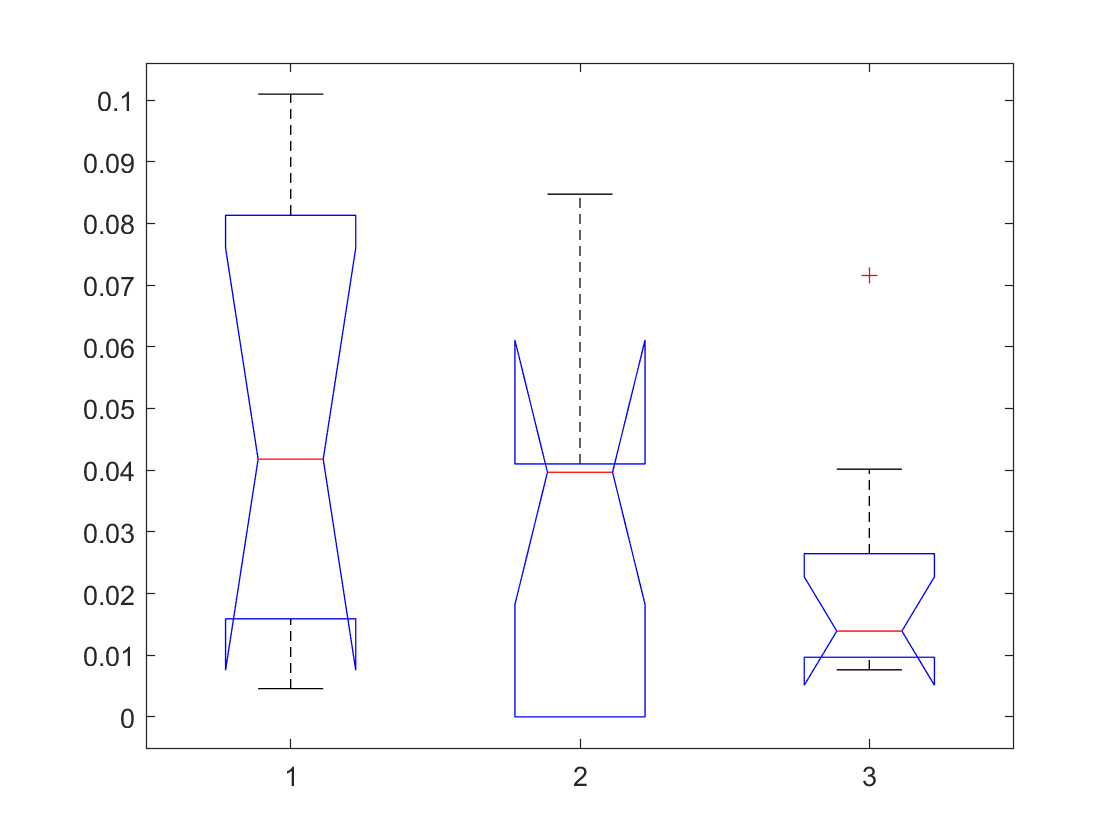

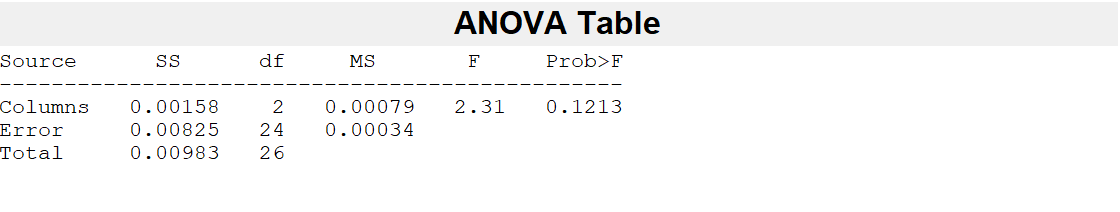

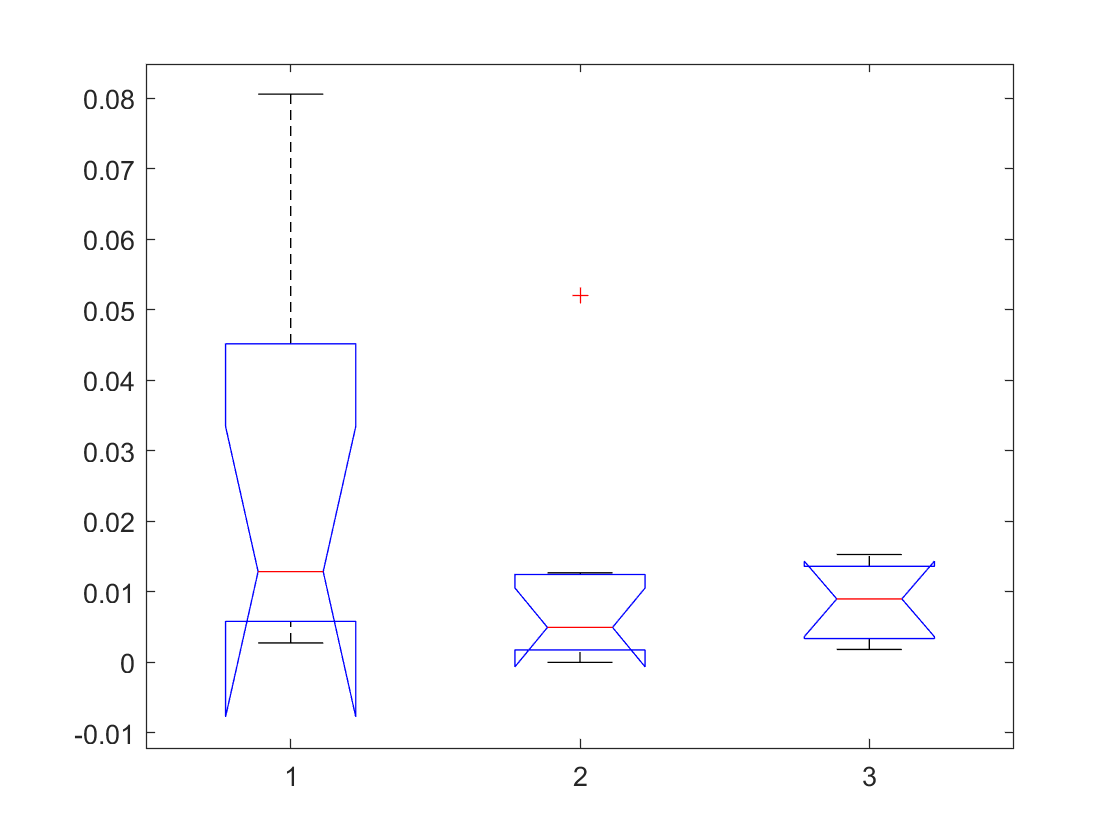

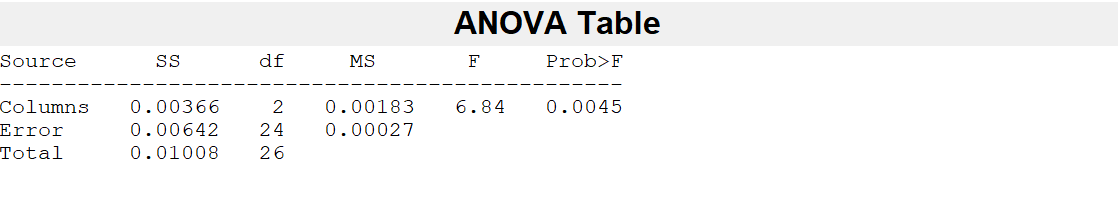

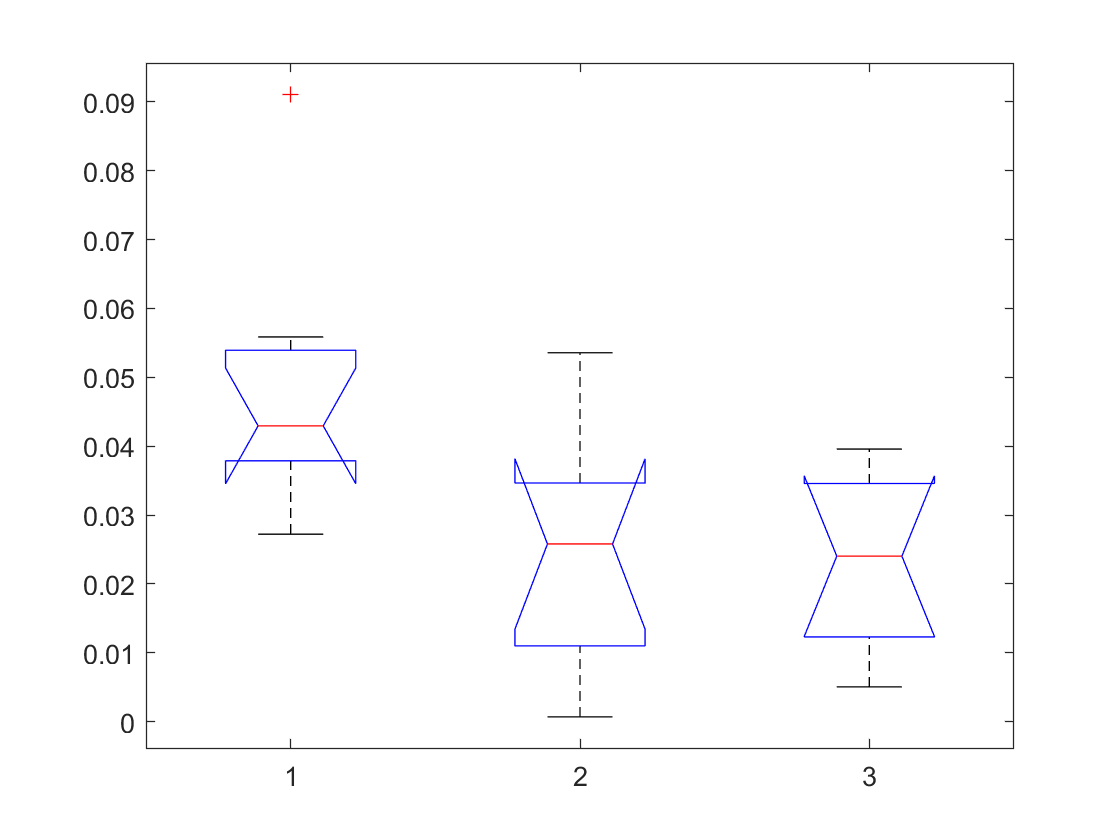

 for i = 1:4
     [a(i) b(i)] = ttest2(septime_mat(:,1,i), [septime_mat(:,2,i) ; septime_mat(:,3,i)]);
      [p(i) t s] = anova1(septimeH_mat(:,:,i));
%     sheetnum = ['Sheet' num2str(i)];
%     xlswrite('SeparationEffectOnPhysical_Sheets_1Agonistic_2groom_3rearsniff_4faceface.xls', septime_mat(:,:,i), sheetnum);       
 end

a

a =      0     0     1     0


b

b =     0.2506    0.2022    0.0017    0.6772


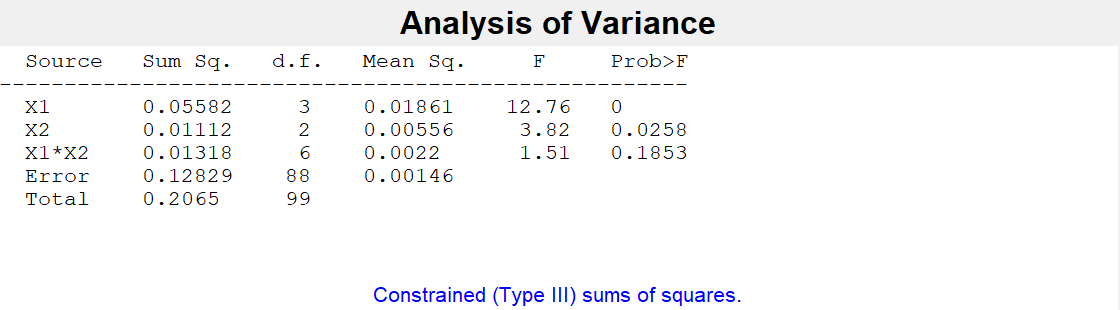


 
 s = septime_mat(:,1:3,:);
 be = ones(size(s));
 for i = 1:size(s,3)
     be(:,:,i) = i;
 end
 cn = repmat(1:size(s,2), size(s,1), 1, size(s, 3));
 
 sr = reshape(s, size(s,1)*size(s,2)*size(s,3), 1);
 br = reshape(be, size(s,1)*size(s,2)*size(s,3), 1);
 cr = reshape(cn, size(s,1)*size(s,2)*size(s,3), 1);
 
 
 [p t s] = anovan(sr, [br cr], 'model', 'interaction');

 
 figure
 for i = 1:4
%     f2B = subplot(4,3,i*3);
    f2B = subplot(4,1,i);
     %bar(1:3, nanmean(septime_mat(:,:,i)));
     hold on
     e_sub = errorbar(1:3, nanmean(septime_mat(:,:,i)), nanstd(septime_mat(:,:,i))/sqrt(size(septime_mat,1)-1), 'k'); %'LineStyle', 'none');
%    ax = gca;
%    ax.Clipping = 'off';
    set(f2B, 'XTick', [1:3]);
     set(f2B, 'XTickLabel', xticklabels);
  %  set(get(f1B, 'XLabel'), 'String', 'condition');
 %   set(get(f1B, 'YLabel'), 'String', 'proportion of time');
    set(get(f2B, 'Title'), 'String', behaviortypes{i});
    set(get(e_sub, 'Parent'), 'XLim', [.7 3.3]);
     box off
 end

 
  for i = 1:4
     [a(i) b(i)] = ttest2(septimeH_mat(:,1,i), [septimeH_mat(:,2,i) ; septimeH_mat(:,3,i)]);
    
%     sheetnum = ['Sheet' num2str(i)];
%     xlswrite('SeparationEffectOnPhysical_Sheets_1Agonistic_2groom_3rearsniff_4faceface.xls', septime_mat(:,:,i), sheetnum);       
 end
a

a =      0     1     1     1


### B.3 Distribution over time

#### B.3.a first half of session

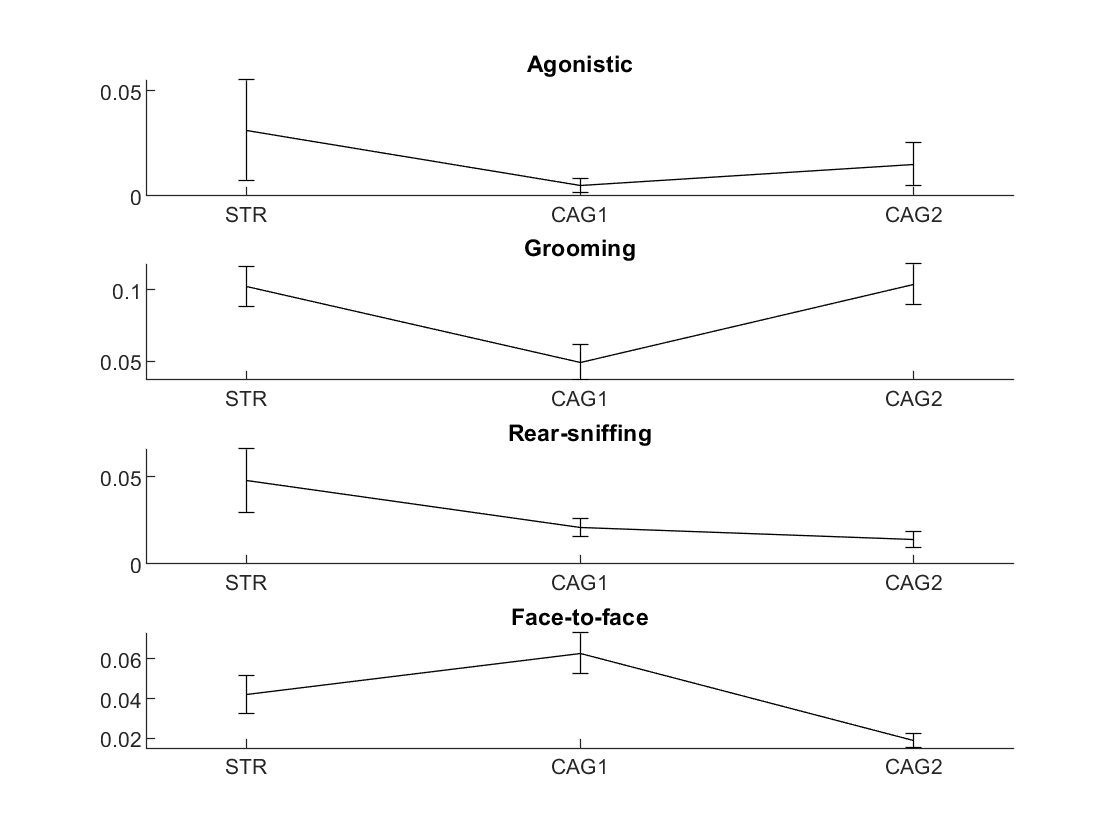

sumbehav_half =  reun_mksumbehav(rdb, betypes, 1, 600);

septimeH_mat = nan(max(scofind),length(cofind),length(phystypes));
 for i = 1:max(scofind)
    for j = 1:length(cofind)        
         if length(cofind{j}) >= i
             septimeH_mat(i,j,1:length(phystypes)) = sum(sumbehav_half(cofind{j}(i),:),1);
         end
    end
 end
 

figure
 for i = 1:4
%     f2B = subplot(4,3,i*3);
    f2B = subplot(4,1,i);
     %bar(1:3, nanmean(septime_mat(:,:,i)));
     hold on
     e_sub = errorbar(1:3, nanmean(septimeH_mat(:,:,i)), nanstd(septimeH_mat(:,:,i))/sqrt(size(septimeH_mat,1)-1), 'k'); %'LineStyle', 'none');
%    ax = gca;
%    ax.Clipping = 'off';
    set(f2B, 'XTick', [1:3]);
     set(f2B, 'XTickLabel', xticklabels);
  %  set(get(f1B, 'XLabel'), 'String', 'condition');
 %   set(get(f1B, 'YLabel'), 'String', 'proportion of time');
    set(get(f2B, 'Title'), 'String', behaviortypes{i});
    set(get(e_sub, 'Parent'), 'XLim', [.7 3.3]);
     box off
 end

clear a b
 for i = 1:4
     [a(i) b(i)] = ttest2(septimeH_mat(:,1,i), [septimeH_mat(:,2,i) ; septimeH_mat(:,3,i)]  );
%     sheetnum = ['Sheet' num2str(i)];
%     xlswrite('SeparationEffectOnPhysical_Sheets_1Agonistic_2groom_3rearsniff_4faceface.xls', septime_mat(:,:,i), sheetnum);       
 end
 
 a

a =      0     0     1     0


 b

b =     0.2337    0.1617    0.0336    0.9834


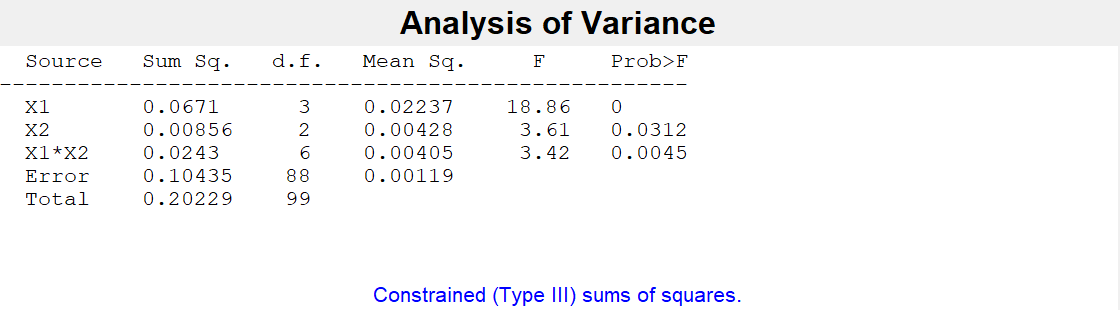

 
 s = septimeH_mat(:,1:3,:);
 be = ones(size(s));
 for i = 1:size(s,3)
     be(:,:,i) = i;
 end
 cn = repmat(1:size(s,2), size(s,1), 1, size(s, 3));
 
 sr = reshape(s, size(s,1)*size(s,2)*size(s,3), 1);
 br = reshape(be, size(s,1)*size(s,2)*size(s,3), 1);
 cr = reshape(cn, size(s,1)*size(s,2)*size(s,3), 1);
 
 
 [p t s] = anovan(sr, [br cr], 'model', 'interaction');

### B.3.b Temporal distribution 

% A.Cumulative activity over time

cumsum_f_a_d1 = nan(max(scofind), 601, length(cofind));
h_cs_f_a = nan(max(scofind), length(cofind));
 
 for i = 1:max(scofind)
    for j = 1:length(cofind)        
         if length(cofind{j}) >= i
            cumsum_f_a_d1(i,:,j) = cumsumbehav(cofind{j}(i),:);
            h_cs_f_a(i,j) = cumsumbehav_ht(cofind{j}(i));
         end
    end
 end
 

Display cumsums

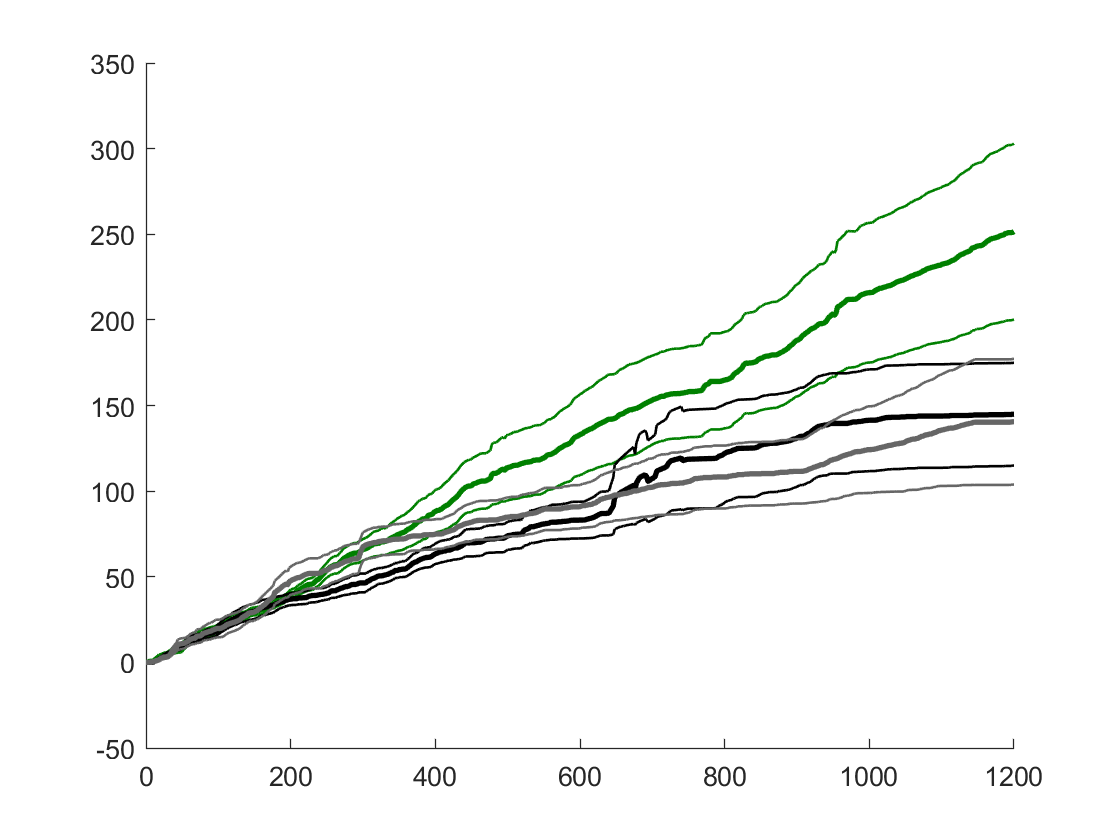

% errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(length(u_paircodes)-1), 'k:');
% hold on
% errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(length(u_paircodes)-1), 'k--');
% errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(length(u_paircodes)-1), 'k-');
% 


figure
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(max(scofind)-1), 'Color', [0 .5 0]);
hold on
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(max(scofind)-1), 'Color', [0 0 0]);
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(max(scofind)-1), 'Color', [.4 .4 .4]);

box off


 for i = 1:600
     [a(i) b(i)] = ttest(cumsum_f_a_d1(:,i,1)-cumsum_f_a_d1(:,i,2));
 end
 [min_SHK_CTL locmin_1_45] = min(b)

min_SHK_CTL = 0.0245

locmin_1_45 = 597

  for i = 1:600
     [a(i) b(i)] = ttest(cumsum_f_a_d1(:,i,1)-cumsum_f_a_d1(:,i,3));
  end
  [min_SHK_RWD locmin_1_24] = min(b)

min_SHK_RWD = 0.1419

locmin_1_24 = 455

    for i = 1:600
     [a(i) b(i)] = ttest(cumsum_f_a_d1(:,i,2)-cumsum_f_a_d1(:,i,3));
    end
    [min_CTL_RWD locmin_45_24] = min(b)

min_CTL_RWD = 0.0363

locmin_45_24 = 153

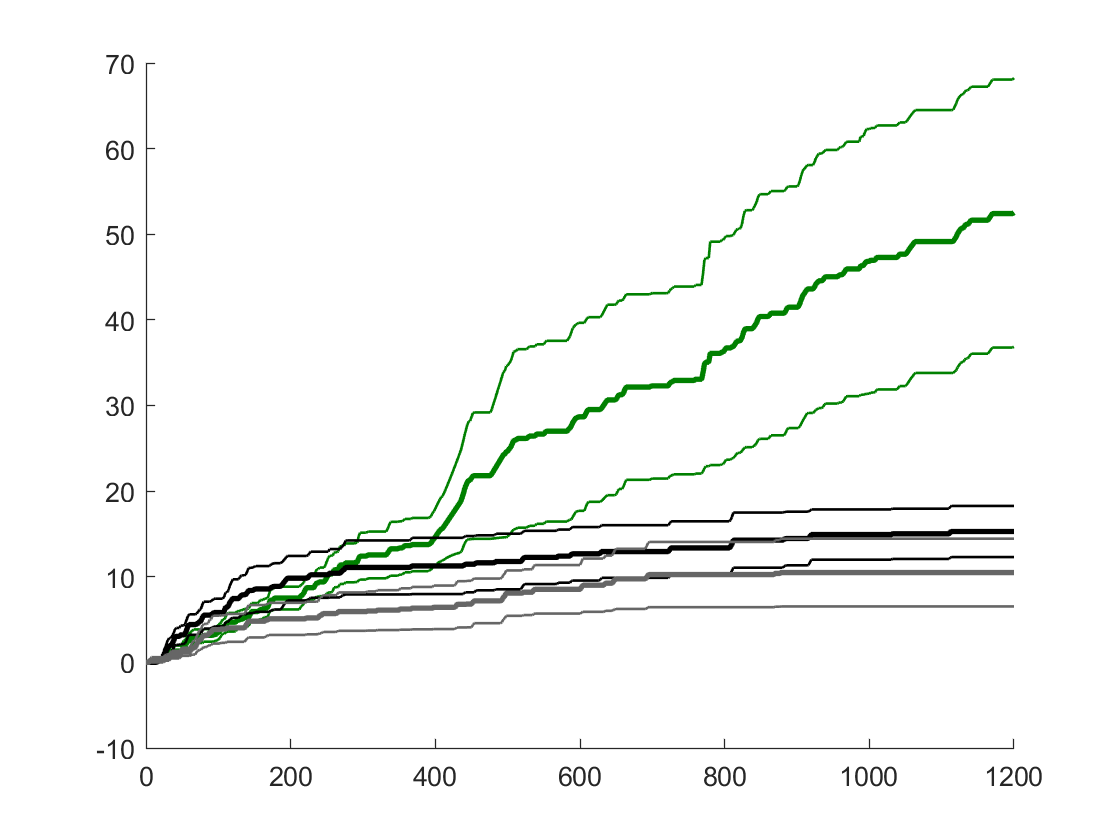

% A.Cumulative activity over time

cumsum_f_RS_d1 = nan(max(scofind), 601, length(cofind));
h_cs_f_RS = nan(max(scofind), length(cofind));
 
 for i = 1:max(scofind)
    for j = 1:length(cofind)        
         if length(cofind{j}) >= i
            cumsum_f_RS_d1(i,:,j) = cumsumbehavRS(cofind{j}(i),:);
            h_cs_f_a(i,j) = cumsumbehavRS_ht(cofind{j}(i));
         end
    end
 end
 
 figure
errorbar_alt(0:2:1200, nanmean(cumsum_f_RS_d1(:, :, 1)), nanstd(cumsum_f_RS_d1(:, :, 1))/sqrt(size(cumsum_f_RS_d1,1)-1), 'Color', [0 .5 0]);
hold on
errorbar_alt(0:2:1200, nanmean(cumsum_f_RS_d1(:, :, 2)), nanstd(cumsum_f_RS_d1(:, :, 2))/sqrt(size(cumsum_f_RS_d1,1)-1), 'Color', [0 0 0]);
errorbar_alt(0:2:1200, nanmean(cumsum_f_RS_d1(:, :, 3)), nanstd(cumsum_f_RS_d1(:, :, 3))/sqrt(size(cumsum_f_RS_d1,1)-1), 'Color', [.4 .4 .4]);

box off

  for i = 1:600
     [a(i) b(i)] = ttest2(cumsum_f_RS_d1(:,i,1), [cumsum_f_RS_d1(:,i,2) ; cumsum_f_RS_d1(:,i,3)]);
 end
 [min_STR_CAG locmin_STR_CAG] = min(b)

min_STR_CAG = 0.0016

locmin_STR_CAG = 587

Compare latency to half-amplitude

[a b] = ttest2(h_cs_f_a(:,1), [h_cs_f_a(:,2) ; h_cs_f_a(:,3)])

a = 1

b = 0.0215

### B.4 Temporal relationships between interaction types

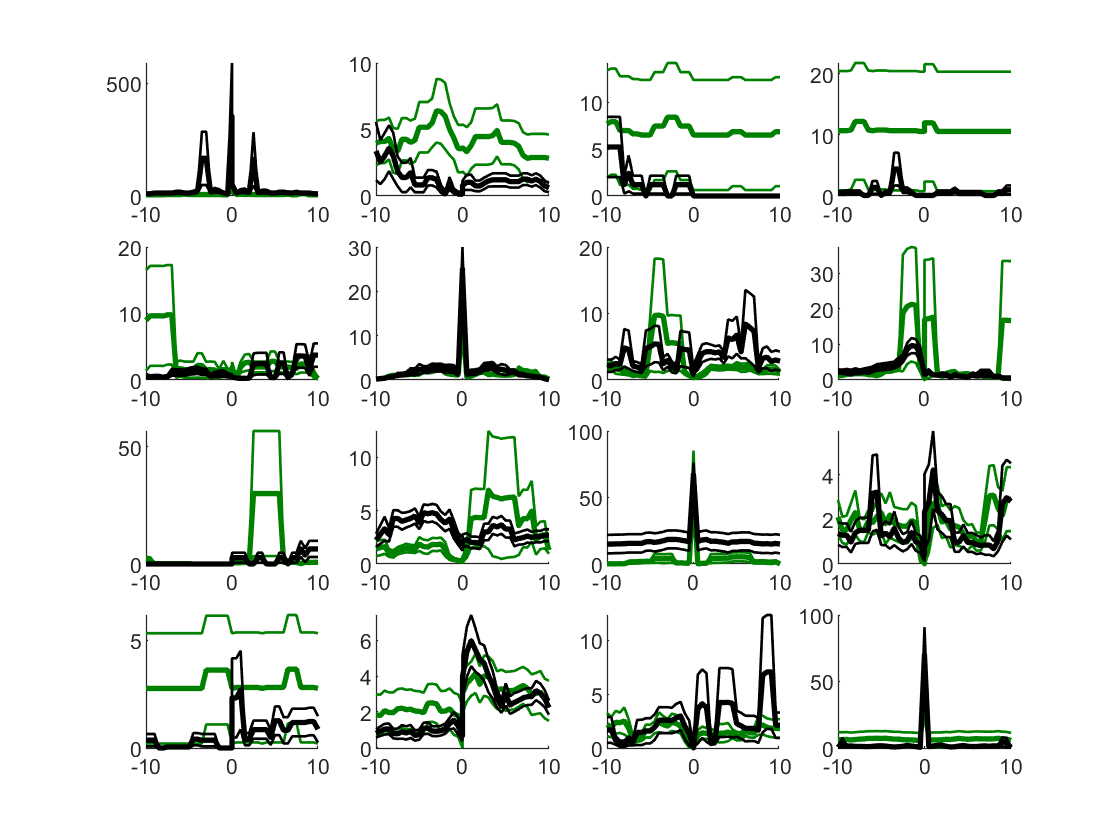

colorcodes = [0 .5 0; 0 0 0; .5 .5 .5];

figure
%i = 1;
for i = 1:2
    for j = 1:16
        subplot(4,4,j);
        hold on        
        if i == 2
            cc = colorcodes(2,:);
            curind = [cofind{i}' ; cofind{i+1}];
        else 
            curind = cofind{i};
            cc = colorcodes(1,:);
        end
        errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(j,:,curind))'), nanstd(squeeze(be_xcorr(j,:,curind))')/sqrt(length(curind)-1), 'Color', cc)  ;  
%        hold on
%        errorbar_alt(xaxis, nanmean(squeeze(SH_xcorr(j,:,curind))'), nanstd(squeeze(SH_xcorr(j,:,curind))')/sqrt(length(curind)-1), 'Color', colorcodes(2,:))  ; 
        box off
    end    
    
end


mxc = nan(size(be_xcorr,1), 2, size(be_xcorr,3));

mxc(:,1,:) = nanmean(be_xcorr(:,1:19,:),2);
mxc(:,2,:) = nanmean(be_xcorr(:,23:42,:),2);

sxc(:,1,:) = nanmean(SH_xcorr(:,1:19,:),2);
sxc(:,2,:) = nanmean(SH_xcorr(:,23:42,:),2);

cofind;

for i = 1:16
    [asi1(i), bsi1(i)] = ttest2(squeeze(mxc(i,1,cofind{1})), [squeeze(mxc(i,1,cofind{2})) ; squeeze(mxc(i,1,cofind{3}))]);
end

for i = 1:16
    [asi2(i), bsi2(i)] = ttest2(squeeze(mxc(i,2,cofind{1})), [squeeze(mxc(i,2,cofind{2})) ; squeeze(mxc(i,2,cofind{3}))]);
end

[codes(:,1:2,1) bsi1' bsi2']

ans =     1.0000    1.0000    0.2459    0.2204
    1.0000    2.0000    0.1378    0.1055
    1.0000    3.0000    0.2948    0.1897
    1.0000    4.0000    0.2302    0.2206
    2.0000    1.0000    0.1444    0.9732
    2.0000    2.0000    0.6633    0.4331
    2.0000    3.0000    0.8265    0.0321
    2.0000    4.0000    0.4606    0.1307
    3.0000    1.0000    0.0664    0.3140
    3.0000    2.0000    0.0075    0.3909


## C: Vocalizations

Rather than re-doing this several times, let's make the sepvoctime_mat

out of whichever variable we are most interested at the moment

options are:

sumvoc -- all syllables

nsumvoc -- all syllables, exclusing nans

csumvoc -- syllables combined into "calls"

rsumvoc -- the rate of syllables, rather than the proportion of time (number instead of time) 

%

### C.1 vocalization sums

%A lot of this code comes directly from reunionOTRA2.mlx

sv = rsumvoc; %plug in another option, depending on interest

 sepvoctime_mat = nan(max(scofind),length(cofind));
 vocnum_mat = sepvoctime_mat;
% svt_4 = nan(length(u_paircodes),3,2);
% side_svt = svt_4;

 for i = 1:size(sepvoctime_mat,1)
     for k = 1:length(cofind)
         if length(cofind{k}) >= i
            sepvoctime_mat(i, k) = sv(cofind{k}(i),:);    
            vocnum_mat(i, k) = nsumvoc(cofind{k}(i),:); %this is a weird way to jump back to the voc nums, but moving on 
         end
         
     end
 end

### C.2 vocalization types (manual)

 f = figure

f =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 59
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


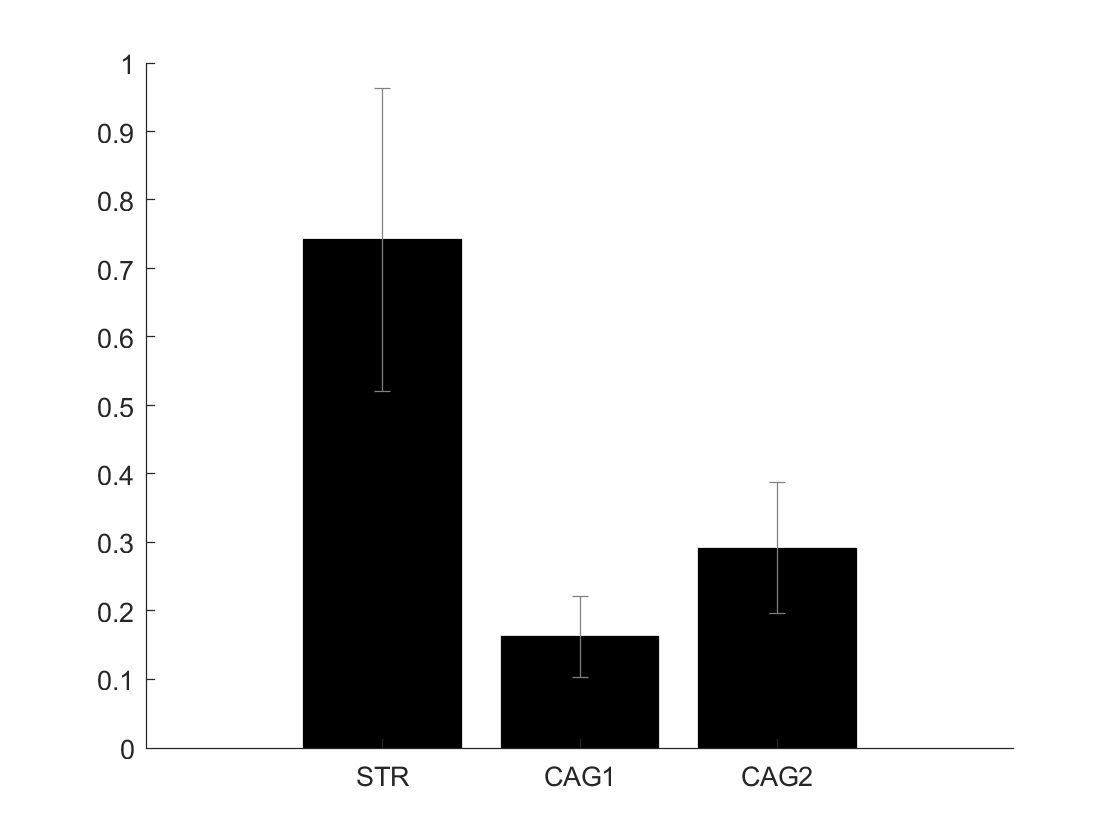

 curmat = sepvoctime_mat;
%curmat = vocnum_mat;

 bar(nanmean(curmat), 'k')
hold on
errorbar(1:3, nanmean(curmat), nanstd(curmat)/sqrt(8), 'Color', [.5 .5 .5], 'LineStyle', 'none')
box off
set(get(f, 'Children'), 'XTick', [1:3])
set(get(f, 'Children'), 'XTickLabel', xticklabels);

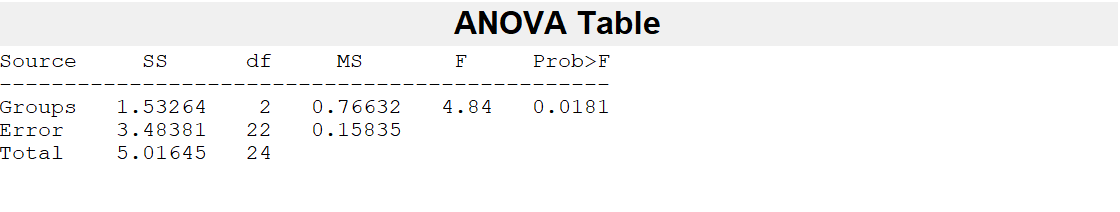

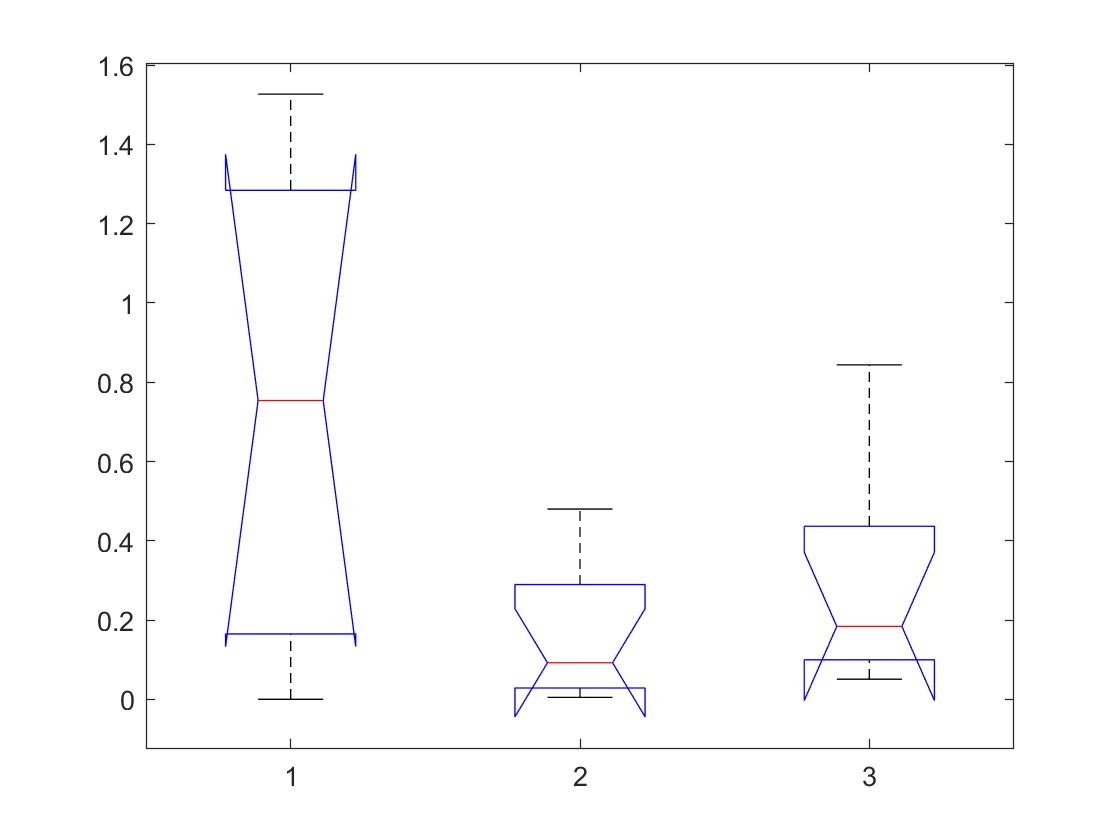

p = anova1(sepvoctime_mat);

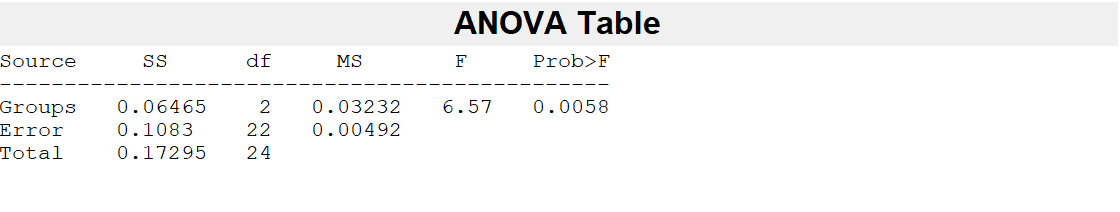

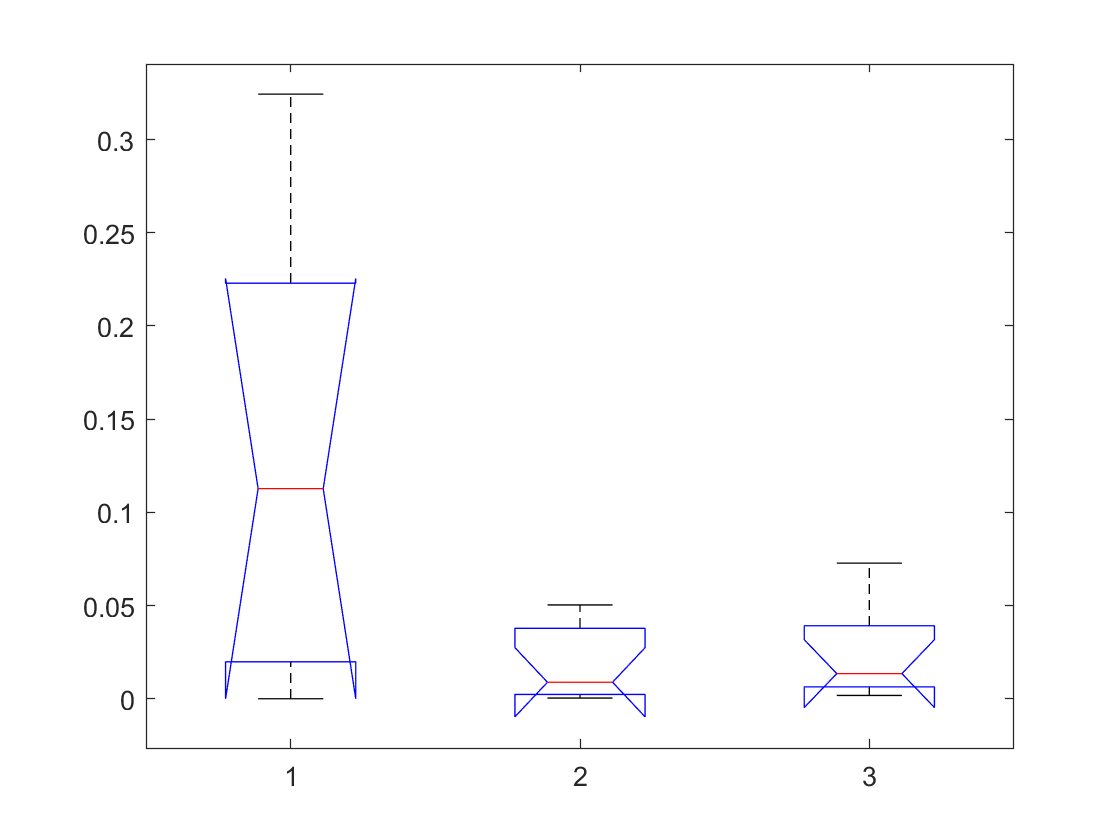


p = anova1(vocnum_mat);


[a b] = ttest2(sepvoctime_mat(:,1), [sepvoctime_mat(:,2) ; sepvoctime_mat(:,3)])

a = 1

b = 0.0054


[a b] = ttest2(vocnum_mat(:,1), [vocnum_mat(:,2) ; vocnum_mat(:,3)])

a = 1

b = 0.0012

sv = rvoc;

sepvoctime_mat_full = nan(size(sepvoctime_mat,1), length(cofind), length(indvocsgood));

 for i = 1:size(sepvoctime_mat,1)
     for k = 1:length(cofind)
         if length(cofind{k}) >= i
             curind = cofind{k}(i);
             sepvoctime_mat_full(i, k, :) = sv(curind,:);    
         end
     end
 end

Figures

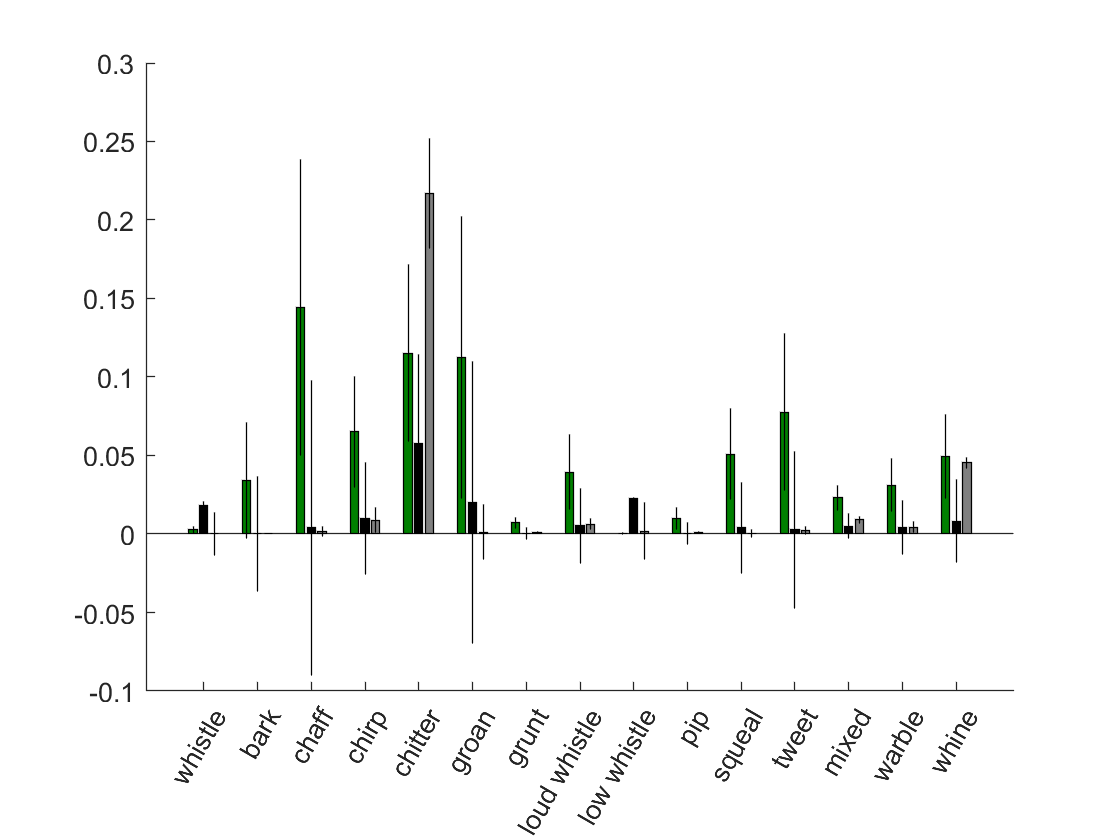

 f4 = figure;
colorcodes = [0 .5 0; 0 0 0; .5 .5 .5];

 hold on
b1 = bar((1:15)-.2, squeeze(nanmean(sepvoctime_mat_full(:,1,:)))', 'BarWidth', .15, 'FaceColor', [0 .5 0]);
b2 = bar((1:15), squeeze(nanmean(sepvoctime_mat_full(:,2,:)))', 'BarWidth', .15, 'FaceColor', [0 0 0]);
b3 = bar((1:15)+.2, squeeze(nanmean(sepvoctime_mat_full(:,3,:)))', 'BarWidth', .15, 'FaceColor', [.5 .5 .5]);
e1 = errorbar((1:15)-.2, squeeze(nanmean(sepvoctime_mat_full(:,1,:)))', squeeze(nanstd(sepvoctime_mat_full(:,1,:) )/sqrt(6)), 'k', 'LineStyle', 'none', 'CapSize', .1);
e2 = errorbar((1:15), squeeze(nanmean(sepvoctime_mat_full(:,2,:)))', squeeze(nanstd(sepvoctime_mat_full(:,1,:) )/sqrt(6)), 'k', 'LineStyle', 'none', 'CapSize', .1);
e3 = errorbar((1:15)+.2, squeeze(nanmean(sepvoctime_mat_full(:,3,:) )), squeeze(nanstd(sepvoctime_mat_full(:,2,:) )/sqrt(6)), 'k', 'LineStyle', 'none', 'CapSize', .1);
%bar([2 4.5 7 9.5], squeeze(nanmean(voctime_mat(:,2,:) )), 'BarWidth', .35);
%errorbar([2 4.5 7 9.5], squeeze(nanmean(voctime_mat(:,2,:) )), squeeze(nanstd(voctime_mat(:,2,:) )/sqrt(6)), 'k', 'LineStyle', 'none');
set(get(f4, 'Children'), 'XTickMode', 'manual')
set(get(f4, 'Children'), 'XTick', 1:15)
ivg = indvocsgood; %([1:6 8:end]);
set(get(f4, 'Children'), 'XTickLabel', rdb.voctypes(ivg))
set(get(f4, 'Children'), 'XTickLabelRotation', 60)

curmat = sepvoctime_mat_full;

s = size(curmat);

toprowDM = cell(1,s(2)*s(3));
idatamat = cell(s(2)*s(3),2);
for i = 1:s(2)
    for j = 1:s(3)
        toprowDM{i+(j-1)*s(2)} = ['B' num2str(i) 'C' num2str(j)]; 
        idatamat{i+(j-1)*s(2),1} = ['B' num2str(i)];
        idatamat{i+(j-1)*s(2),2} = ['C' num2str(j)];
    end
end

datamat = num2cell(reshape(curmat, s(1), s(2)*s(3),1));
full_dm = [[{'subject'} toprowDM] ; [num2cell([1:size(datamat,1)]') datamat]];
T = cell2table(full_dm(2:end,:), 'VariableNames', full_dm(1,:));
writetable(T,'datamat.csv');

To do the stats, need to be running R

%!C:\Program Files\R\R-3.6.1\bin\x64\Rscript

full_idm = [{'B' 'C'} ; idatamat];
iT = cell2table(full_idm(2:end,:), 'VariableNames', full_idm(1,:));
writetable(iT,'idatamat.csv');

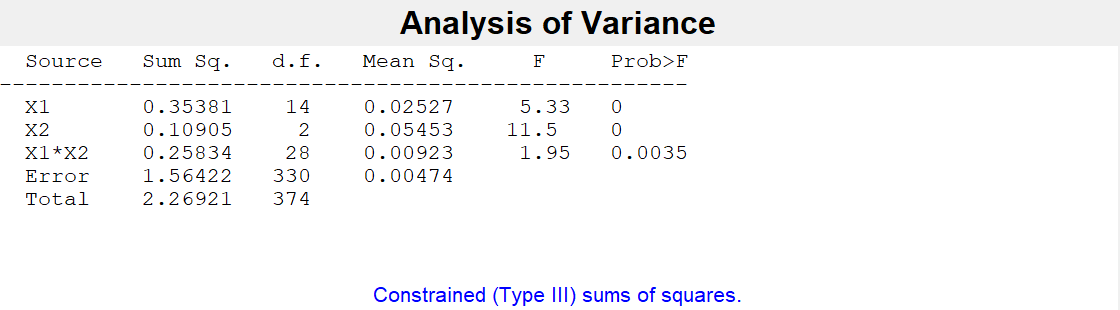

% 2-Way ANOVA for vocalization type

 s = sepvoctime_mat_full(:,1:3,:);
 be = ones(size(s));
 for i = 1:size(s,3)
     be(:,:,i) = i;
 end
 cn = repmat(1:size(s,2), size(s,1), 1, size(s, 3));
 
 sr = reshape(s, size(s,1)*size(s,2)*size(s,3), 1);
 br = reshape(be, size(s,1)*size(s,2)*size(s,3), 1);
 cr = reshape(cn, size(s,1)*size(s,2)*size(s,3), 1);
 
 
 [p t s] = anovan(sr, [br cr], 'model', 'interaction');

for i = 1:15
    [a(i) b(i)] = ttest2(squeeze(sepvoctime_mat_full(:,1,i)), [squeeze(sepvoctime_mat_full(:,2,i)) ; squeeze(sepvoctime_mat_full(:,3,i))]);
end

a

a =      0     0     1     1     0     0     1     1     0     1     1     1     1     1     0


b

b =     0.4680    0.1234    0.0163    0.0158    0.7981    0.0698    0.0085    0.0261    0.3057    0.0373    0.0084    0.0168    0.0054    0.0150    0.2502


b;

sVM_chit = sepvoctime_mat_full(:,:,5);
sVM_nc = nansum(sepvoctime_mat_full(:,:,[1:4 6:end]), 3)

sVM_nc =     0.2863    0.0416    0.0187
    0.8572    0.0422    0.1760
    1.2210    0.2262    0.0059
    1.1936    0.0146    0.0534
    0.0002    0.0228    0.1205
         0    0.2838    0.2307
    0.3236    0.2677    0.0389
    1.2981    0.0434    0.0283
         0    0.0052         0


 nc2c = sVM_nc./sVM_chit;
 nc2c(isinf(nc2c)) = nan

nc2c =     2.4549    0.8597    0.1436
    2.9147    0.3382    0.5916
    3.4780    0.8624    0.1158
   51.1529       NaN    0.3770
    0.0313    1.9464    0.3927
       NaN    7.2447    0.3607
   64.6927   16.9112    0.2670
   10.3044    2.2731    1.1692
       NaN       NaN       NaN


 [a b] = ranksum(nc2c(:,1), [nc2c(:,2) ; nc2c(:,3)])

a = 0.0345

b = logical
   1


### C.3 Distribution over time

 cumsum_f_a_d1 = nan(max(scofind), 601, length(condvec));
h_cs_f_a = nan(max(scofind), length(condvec));
 
 for k = 1:length(cofind)
    for i = 1:max(scofind)
        if length(cofind{k}) >= i
            curind = cofind{k}(i);  
            cumsum_f_a_d1(i,:,k) = cumsumvoc(curind,:);
            h_cs_f_a(i,k) = cumsumvoc_ht(curind);
        end
        
    end
 end
 

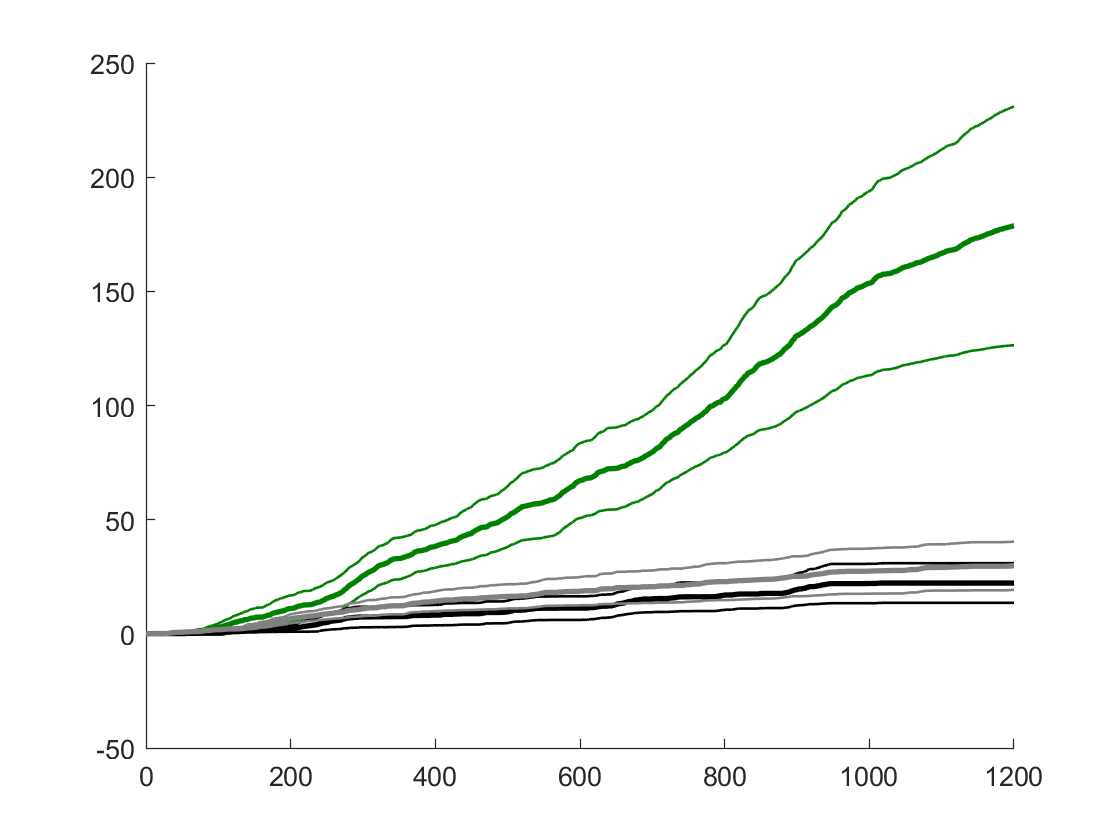

 figure
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(scofind(1)-1), 'Color', [0 .5 0]);
hold on
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(scofind(2)-1), 'Color', [0 0 0]);
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(scofind(3)-1), 'Color', [.5 .5 .5]);

box off

### C.4 Automated clustering of syllables

clear inds

for i = 1:max(scofind)
    for j = 1:3
        if length(cofind{j}) >= i
            curind = cofind{j}(i);
            inds{i,j} = find(indfeat_nn(:,1) == curind); 
%        vip_inds{i,j} = intersect(inds{i,j}, vocind_best);
        end
    end
end

indstouse = cell(length(inds(:,2)) + length(inds(:,3)), 2);
indstouse(1:length(inds(:,1)), 1) = inds(:,1);
indstouse(:,2) = [inds(:,2) ; inds(:,3)];

Assess significance of the clusters

%[pvals_c, ef_c, val_c, irc_m] = sigclust_recursive(idx, indstouse, 1, [], 9);
load strcag_sigclusts

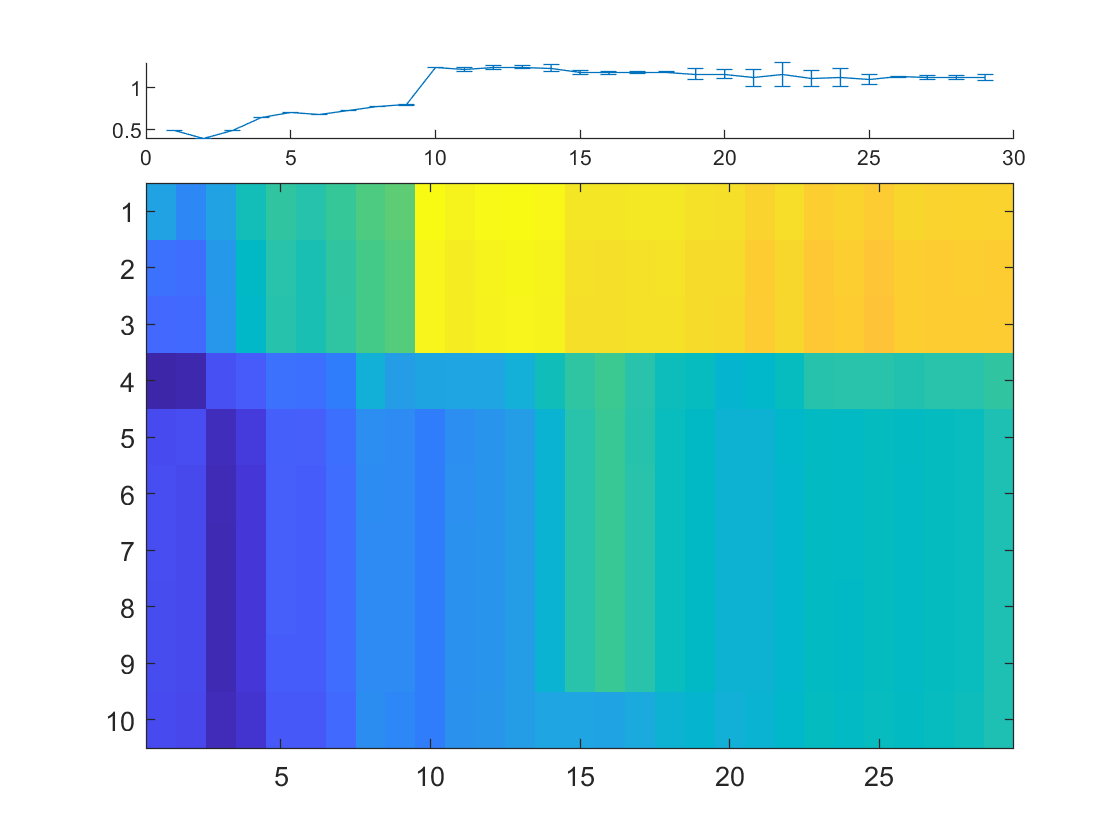

if length(find(~isnan(pvals_c{end}))) == 0
    pvals_c = pvals_c(1:end-1);
    ef_c = ef_c(1:end-1);
    val_c = val_c(1:end-1);
end

[strcag_prevocbest, strcag_vocindbest, strcag_ircm, strcag_nm] = process_sigclusts(pvals_c, ef_c, val_c, idx, indfeat_nn);


strcag_nm

strcag_nm =     0.0058    0.0393    0.0396    0.0720    0.2035    0.0356    0.2029    0.2029    0.2030    0.0042


goodc = 3;

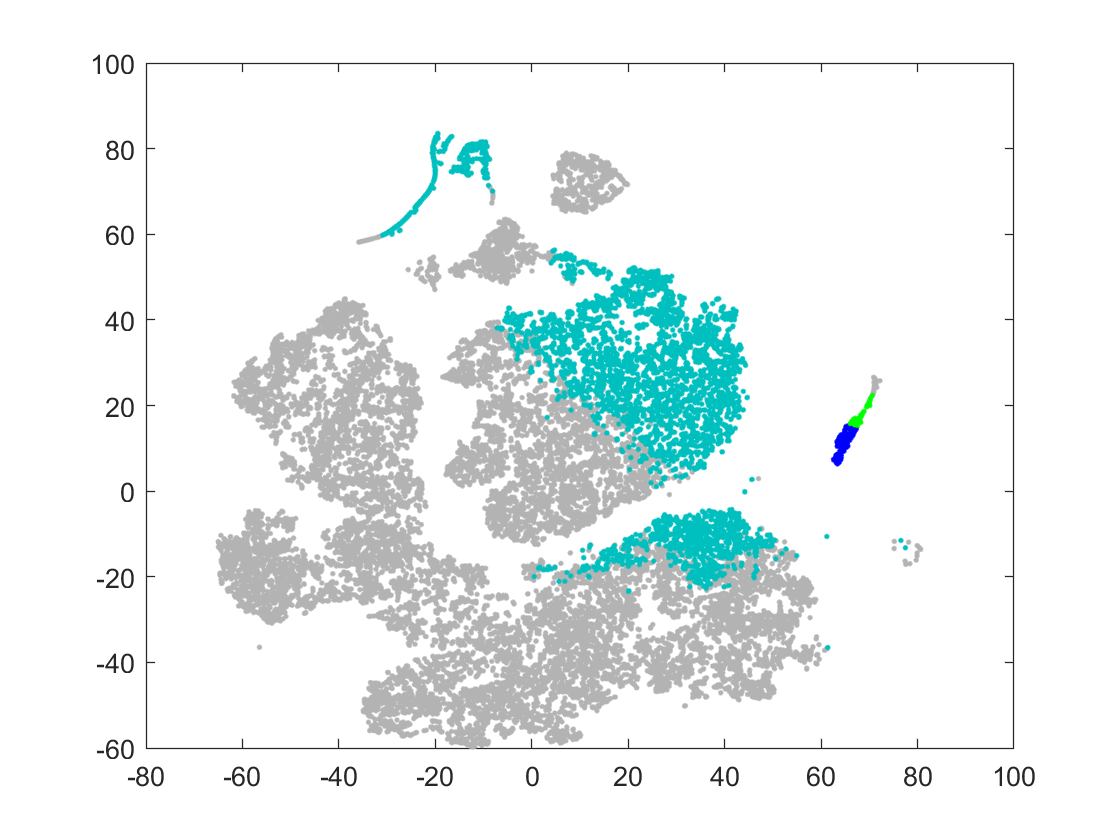

Current plot held


Current plot held


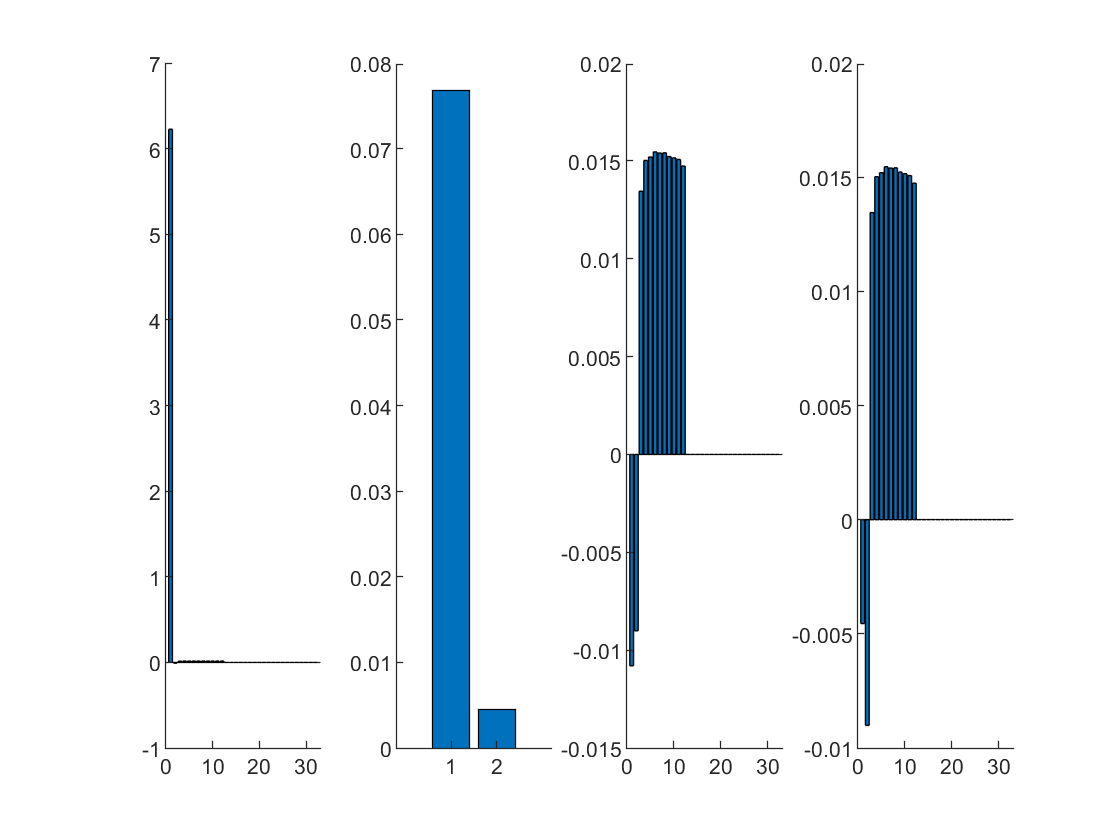

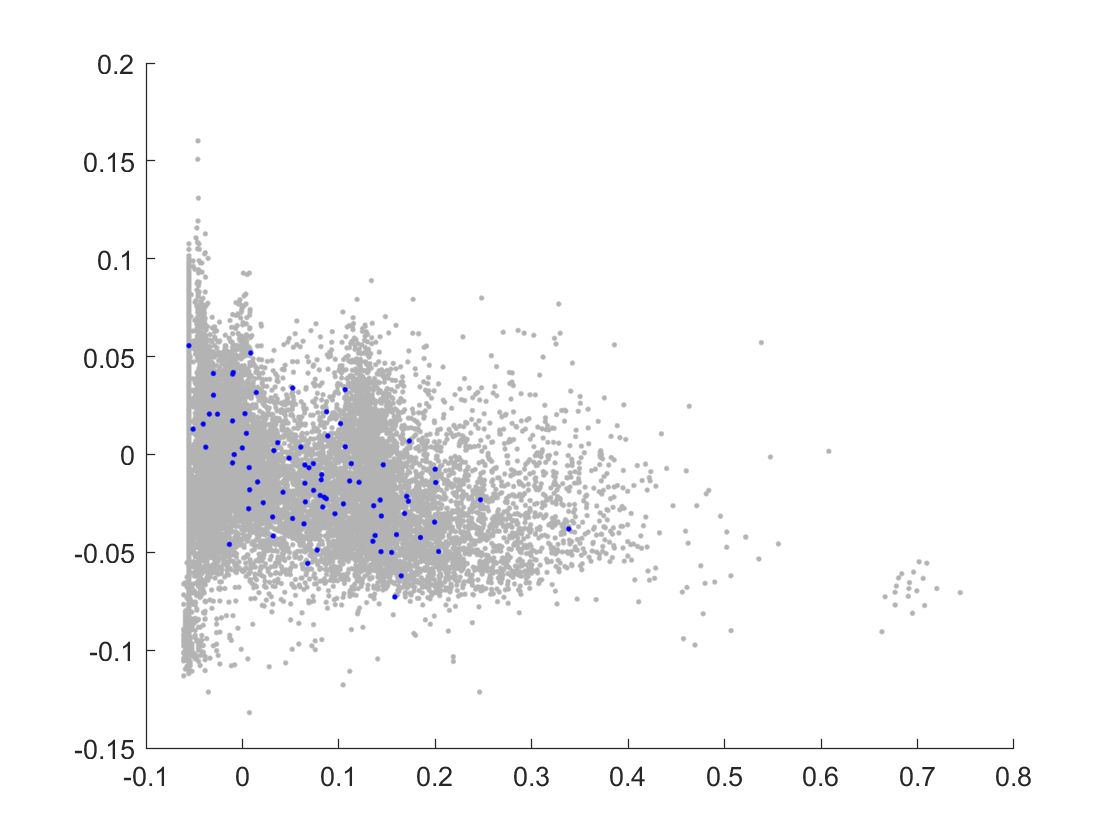

Current plot held


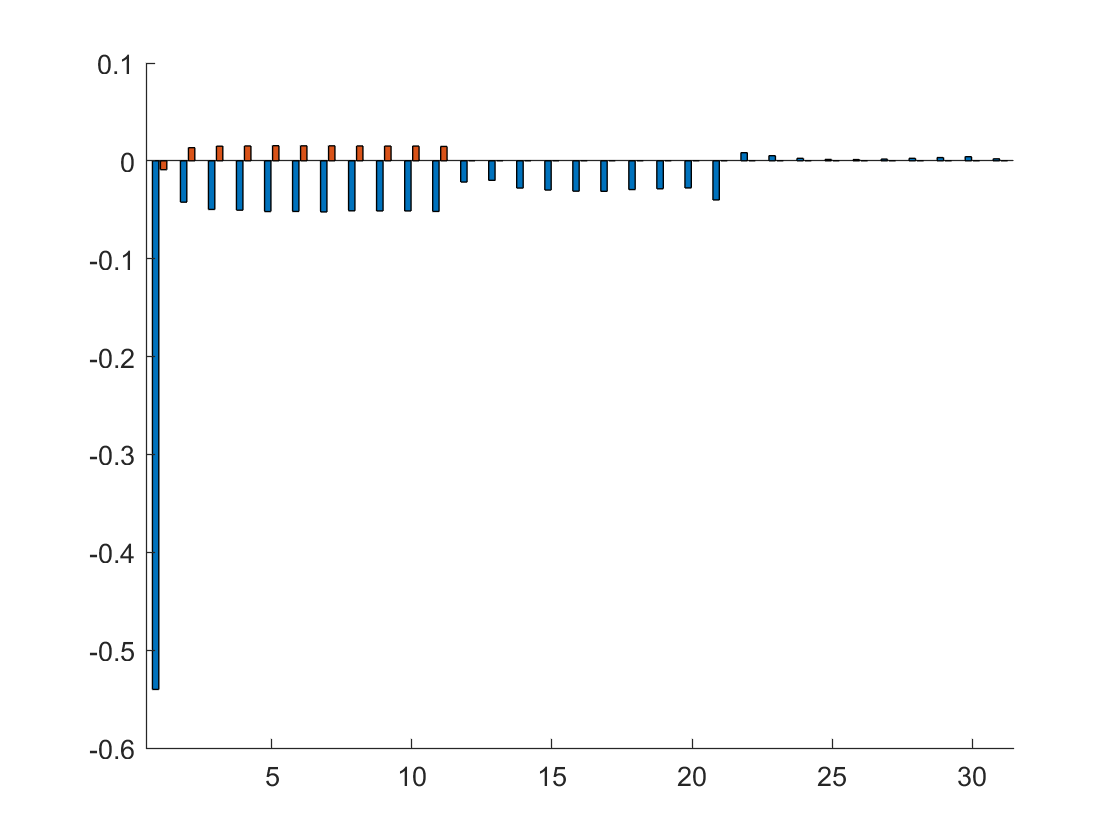

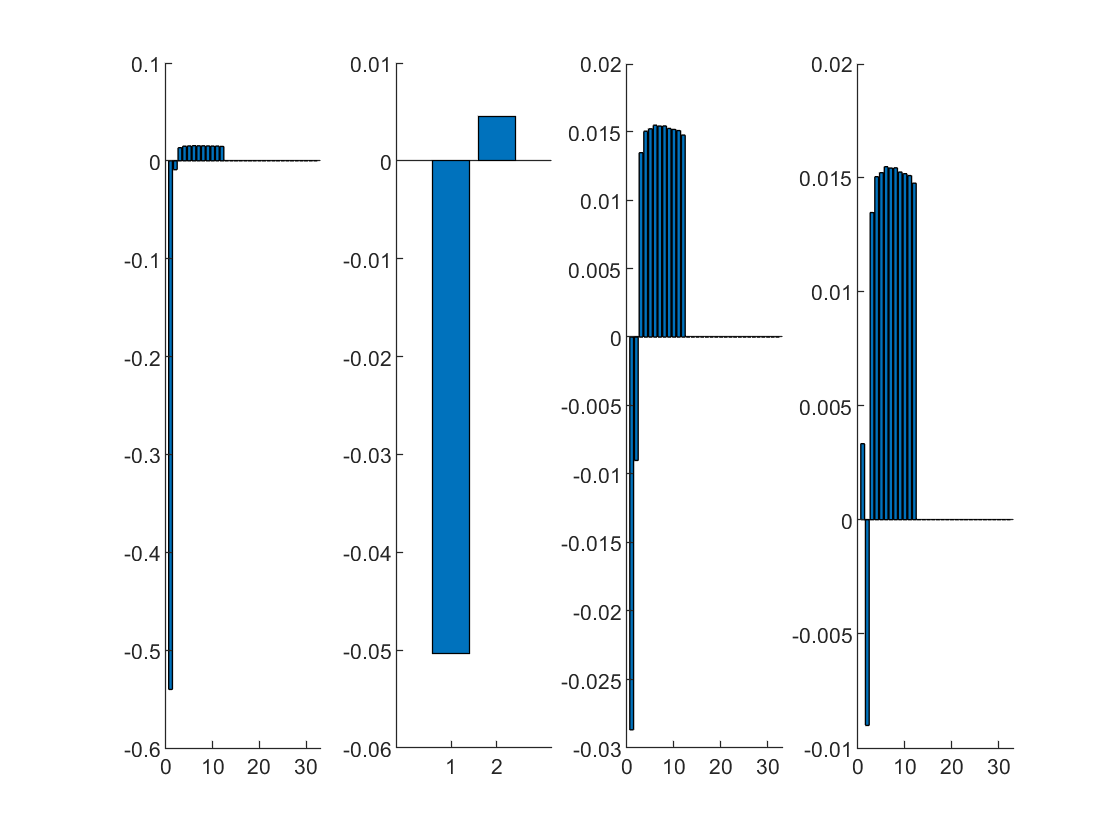

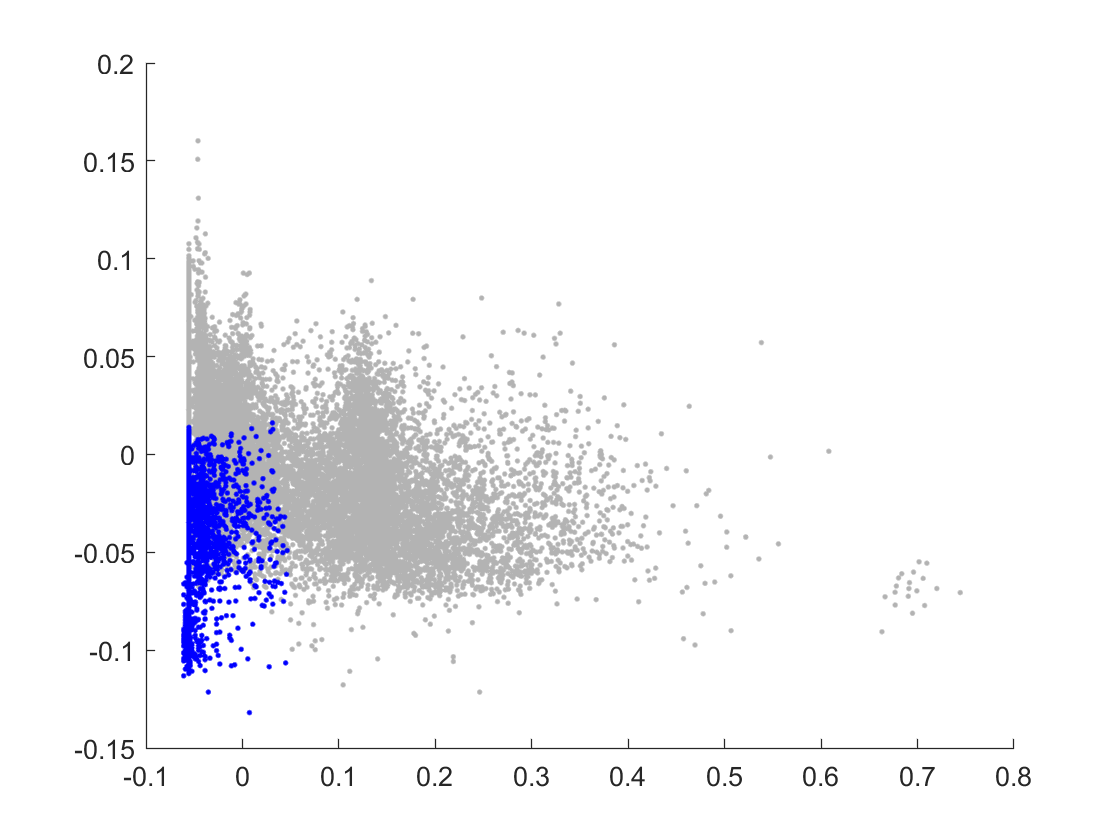

Current plot held


h5 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 78
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


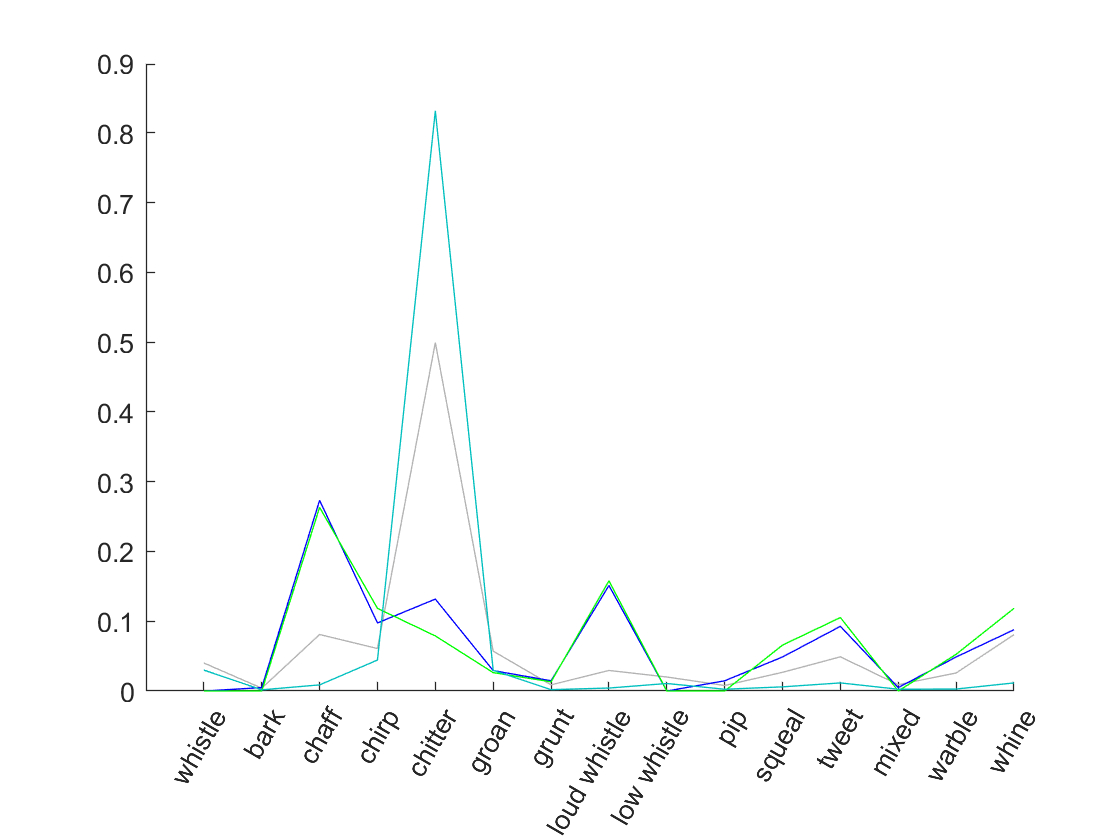

Current plot held


[h1, h2, h3, h4] = sigclust_Figures(strcag_prevocbest, goodc, featset_nn, identcodes_nn, indvocsgood, rdb.voctypes(ivg), y);

### Cross-examine clusters across 3 comparisons

% isosep_prevocbest;
% isosep_vocindbest;
% iso_prevocind;
% iso_vocind;
% iso2_prevocind;
% iso2_vocind;

%

% length(intersect(isosep_prevocbest, iso_prevocind))/length(union(isosep_prevocbest, iso_prevocind))
% %chance overlap
% % Actually: this is difficult to estimate since we have to look only at
% % those syllables expressed in the sessions of interest
% (length(isosep_prevocbest)/length(y) * length(iso_prevocind)/length(y))  /  (length(union(isosep_prevocbest, iso_prevocind)))
% rand_isosep = randperm(length(y), length(isosep_prevocbest));
% rand_iso = randperm(length(y), length(iso_prevocind));
% 
% length(intersect(rand_isosep, rand_iso))/length(union(rand_isosep, rand_iso))
% 
% length(intersect(iso2_prevocind, iso_prevocind))/length(union(iso2_prevocind, iso_prevocind))

sanity check on each:

%strcag_irc(i,:) = [ind_bestclustnum rowmin(1) colmin(1)];

for i = 1:3
    [pvals_c{i}(strcag_ircm(i,2), strcag_ircm(i,1), strcag_ircm(i,3)) ...
        val_c{i}(strcag_ircm(i,2), strcag_ircm(i,1), strcag_ircm(i,3))]
end

ans =     0.0058    0.0248


ans =     0.0319    0.0027


ans =     0.0364   -0.1889
